## Introduction to "chebfun"

In the last two weeks, in order get a solution, there are three types of methods. One is an numerical approximate methods such it is needed to define step size(or sampling points). Without step size to be defined, anthother method is to define a function, specifically an anonymous function (or a matlab command ode15, ode45 and so on). The last one is to deal with in the  symbolic math in Matlab, which is an analytic , or closed form of solution.

Around 2000 year, another computation method is announced as "**chebfun**"(https://www.chebfun.org/) This was invented by Oxford University in UK in applied mathematic department. Their idea is to get an approximate solution, instead of generating a sequence of the variable, use **functions**. You may remember Fourier sin and cosine series, which is able to decompose almost all continuous functions into two functions of sin and cosin. This is due to the fact such that, sin and cosin is one of the orthogal functions. Their idea is that the decomposition functions is not the sin and cos but the "chebyshev" functions which are the solution to a certain non-linear differential equation. I think it is another opition to solve a numerical approximation. Using their methods (in the matlab domain) some good features are there. Let us to study their methods. The simple and basic difference is, I think to capute a core difference , to draw a graph. Consider we need draw a graph of . Let us remind of drawing a graph as 

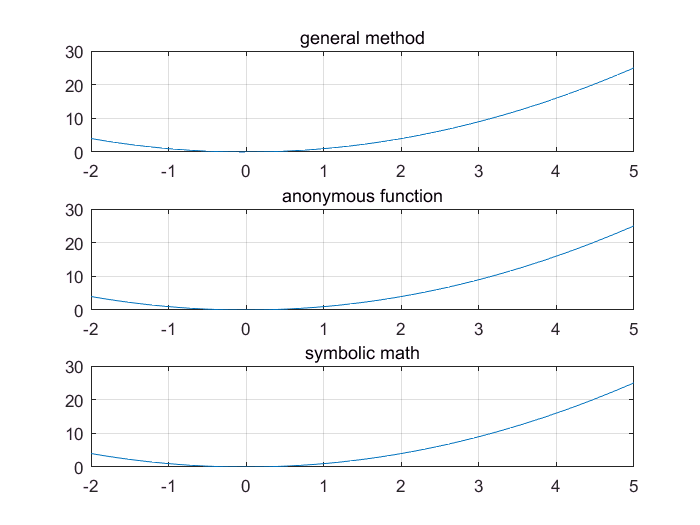

clear all; clc;clf
% general method
x =linspace(-2,5,100);   
f = x.^2;
figure('Renderer', 'painters', 'Position', [10 10 300 200])
figure(1)
subplot(3,1,1); plot(x,f); title('general method')
axis([-2 5 0 30]); grid on
% anonympous function
h = @(x) x.^2;
subplot(3,1,2); fplot(h,[-2 5]);title('anonymous function')
axis([-2 5 0 30]); grid on
%symbolic method
syms y
g = y^2;
subplot(3,1,3); 
fplot(g,[-2 5]); title('symbolic math')
axis([-2 5 0 30]); grid on

Here there are three identical  graphs. However you may see the draw command as "plot" or "fplot".What are the data/variables type?

whos

  Name      Size             Bytes  Class              Attributes

  f         1x100              800  double                       
  g         1x1                112  sym                          
  h         1x1                 32  function_handle              
  x         1x100              800  double                       
  y         1x1                112  sym                          



Here double means real number, function_handle is a function, and y and g are symbolic expressions. Hence in matlab to draw real numbers (complex numbers also), "plot" command is used, however function handle or symbolic, "fplot" command is used. So in order to draw a graph, you should use "right' command not to have an error.

**Basic difference of "chebfun"**

In matlab environment, or domain, the main object is "numerical calculation", i.e., to solve a mathmatical formualtion, calculations are done under the number operations.

So  to draw a graph for $y = x^{2}, x \in [-2 \ 5]$, the step size should be defined. Let us define a step size as 1, then if we index it as 


$$x(1) = -2, x(2) = -1,...,\ x(8) =5.$$


Substituting $x(i) $ to  $y(i)$ given a relation ,  we get the pairs in $(x, y)$ co-ordinates. Ok. in here you just get pairs. What does this mean? The original function is continous but it may be approxmated by some finite numbers as


$$y(t) \ == [y(1), y(2),..., y(n)]$$


So, the continous function is approximated by the discretization! This is the fundamental.  In mathematical calculus the domain(or Uclidean Space) ther are only two operators as 

                                                           $+$  and - 

Every operator shoud be interpreted by thess two operators, as


$$\times, \div , d(  )/dt , \int (  \ ) dt $$


Or other things in your previous study. Now "chebfun" method is different from this step size dependency. In stead of step, it approximate by functions, especially "chebshev functions". 

**Chebyshev polynomials **

Consider the following second order non-linear differential equation


$$(1-x^{2}) \frac_{d^{2}y}{dx^{2}} - x \frac_{dy}{dx} + n^{2}y = 0, n=1,2,3,...$$


this is called a chebyshev differential equation. The solution are , for $n = 1,2,3,...$


$$T_0 (x) =1, T_1 (x) = 1\\
T_2 (x) = 2x^{2} -1 , T_3(4) = 4x^{3} - 3x$$


These polynomials are called chebyshev polynomials, and there are orthogonal to each other in $[ -1  \ 1]$. The Oxford people are developed a new approximation way such as given a function $f(x) $


$$f(x) = \sum_{n=0}^{\infty} a_nT_n(x)$$


where $a_k $ is determined by


$$a_k = \frac_{2}{\pi} \int_{-1}^{1} \frac_{f(x) T_k (x)}  {\sqrt{1-x^2}}\, dx $$


Hence, $f(x)$ can be approxiamted by $T_n (x)$. .. So the previous approximation is done by discretiztion, however it is approximated by functions, especially chebyshev polynomials.

**Draw a grpah using 'chebfun"**

Now I will introduce "chebfun" to you. Let us draw the same graph. then matlab code is 

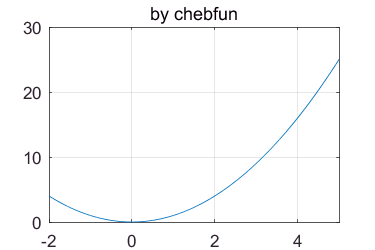

clear all; clf;
s = chebfun(@(x) x^2);   %s =chebfun('x^2') is the same 
figure('Renderer', 'painters', 'Position', [10 10 300 200])
plot(s,[-2 5]); grid on
title('by chebfun')
axis([-2 5 0 30]); grid on

Here in the first line, the command is "chebfun(@(x), x^2)", where the leading syntext is "chebfun" and the following is "@" which is similar to define an anonymous function. And in order to draw the graph, the command is "plot" which is the same as in general case!!(remember in anonymous case fplot  is used). What is the logic in the background of this code? In data type, you define sampling points, which is a **vector**, but in chebfun case, they use **"chebyshev" functions**. How is it done? there are many, complicate mathematical theories. But I think, forget the back grounds but just use it as one of the matlab commands.

**Piecewise smooth chebfuns**

to make a piece wise smooth function using "chebfun" is a little bit simple, as

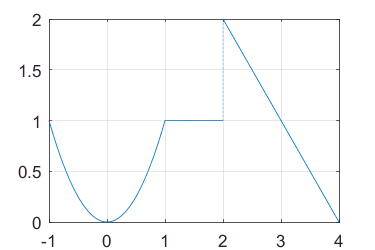

clear all;
f = chebfun({@(x) x^2, 1, @(x) 4-x}, [-1 1 2 4]);
plot(f); grid on

We may know a uniform probability density  function on $ \x \in [ a  \ b]$ as


$$
  f(x)=\begin{cases}
    \frac{1}{b-a}, & \text{if $  a<x<b$}.\\
    0, & \text{otherwise}.
  \end{cases}
\end{equation}$$


To draw$f(x)$ 

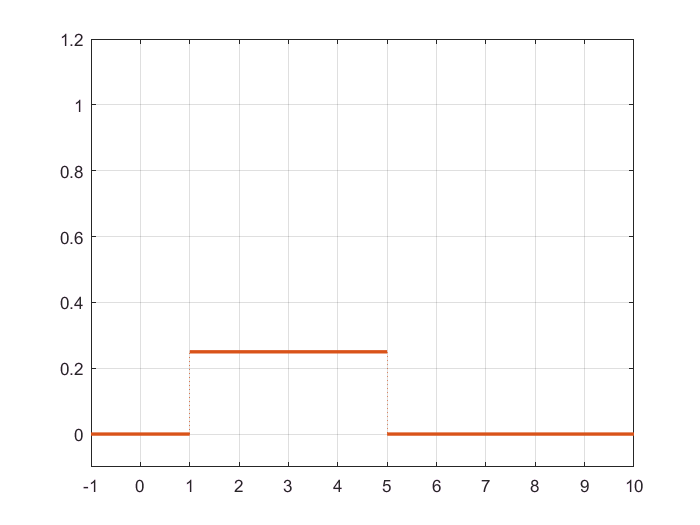

clear all
a =1; b = 5;
LW ='linewidth';
f = chebfun({@(x) 0, 1/(b-a), 0},[-inf  1 5 inf]);
plot(f, LW,2); grid on ; hold on
axis([-1 10 -0.1 1.2])

Now by definition on the probability 


$$\int_{-\infty}^{\infty}  f(x) dx = 1$$


to check in matlab as

sum(f,[-inf, inf])

ans = 1

Here to calculate a definite integral, we may use 

                     integral(   ) 

or 

                    int(  )  % in the case of symbolic math.

However in "chebfun" , the definite integral is as "sum" command. And in case of Probability Distribution Function ( or Cumulative Function) which can be evaluated by 


$$F(x)  = \int_{-\infty}^{x} f(x')dx'$$


Then the matlab code is 

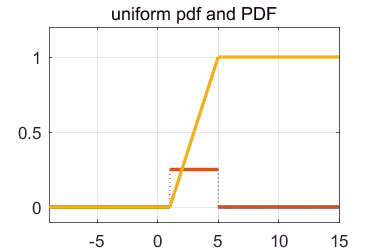

% x = chebfun(@(x) x)
F = cumsum(f);
plot(F, LW,2)
title('uniform pdf and PDF')
hold off

Is it wonderful? Of course to calculate an implicite integral without 'chebfun", you may code to get it but it is complicate, however, one of the merits of 'chebfun" is this simplicity. Here in the case of vector, "cumsum" is the cumulative sum. Another example, consider an exponential pdf and PDF, with different $\lambda = 1,2,3,4$


$$f(x) = \lambda e^{-\lambda x},  \lambda > 0$$


and

 
$$F(x) =\int_{-\infty}^{x} \ f(x')dx'$$
 

can be coded as 

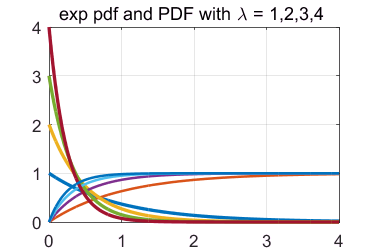


clear all; clf
LW = 'linewidth';
for lamb = 1:4
    f = chebfun(@(x) lamb*exp(-lamb*x), [0 4]);
    plot(f,LW,2); hold on; grid on
    title('exp pdf and PDF with \lambda = 1,2,3,4 ')       
    g = cumsum(f);
    plot(g,LW,1.5); 
end
hold off

Now one of the most famous and complicate PDF is a Gaussian PSF as


$$f(x)  = \frac{1}{\sigma \sqrt{2\pi}} e^{\frac{-(x-m)^2}{2\sigma^2}$$


and 


$$F(x) =\int_{-\infty}^{x} \ f(x')dx'$$


may be

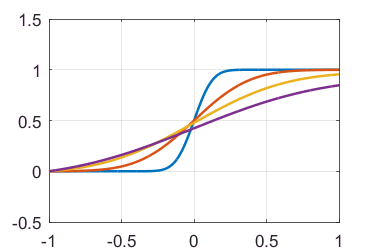

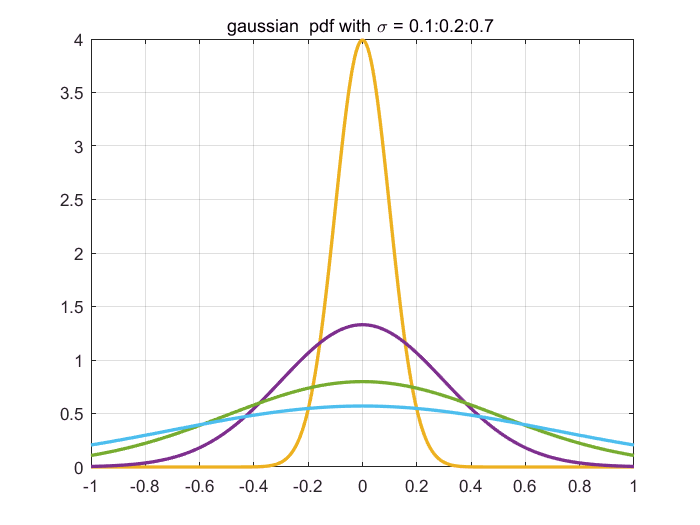

clear all; clf
LW = 'linewidth';
m = 0;
for sigma = 0.1:0.2:0.7
    f = chebfun(@(x) 1/(sigma*sqrt(2*pi))*exp(-(x-m)^2/(2*sigma^2))); 
    figure(1)
    plot(f,LW,2); hold on; grid on
    title('gaussian  pdf with \sigma = 0.1:0.2:0.7 ')
    figure(2)
    g = cumsum(f);
    plot(g,LW,1.5); hold on ; grid on
end

If you draw a gaussian PDF without "chebfun",  you may use a special command or make a code, **which is really complicate**. I think so. However, with "chebfun", it is **simple! **

**Solve algebraic equation **

Last week, in Tut_2, a code to solve an algebraic equation, for example consider the following

algebraic equation 

   
$$x^3 - 6x^2 +11x -6=0$$


to find solution, you may use symbolic math as

syms x
solve(x^3 - 6*x^2 + 11*x -6)

$$ans = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$

In "chebfun", it's code may be

clear all
x = chebfun(@(x) x, [-inf inf]);
f = x^3 -6*x^2 + 11*x -6;
r = roots(f)

r =     1.0000
    2.0000
    3.0000


Or if you define a domain as $x \in [ -1  \ 1]$

clear all
domain =[-1 1];
x = chebfun(@(x) x, domain);
f = x^3 -6*x^2 + 11*x -6;
r = roots(f)

r = 1

So in the domian, there is only one , unique solution. 

**Solve a algebraic system equatio                  n Not good by Chebfun**

In the previous Tut_2, we may solve a algebraic system equation as


$$x+ 2y = -1\\2x +y = 1$$


the solution can be found as

clear all;
syms x y
eqn1 = x+2*y ==-1;
eqn2 = 2*x+y ==1;
S = solve(eqn1,eqn2);
S.x

$$ans = 1$$

S.y

$$ans = -1$$

In this case, the values to satisfy a algebraic system equation are som numbers. However, chubfun is an approximation of a function not a number. So **it is not good to solve this algebraic equation using chebfun!**

**Solve a linear system equation as a matrix inversion**

In the previous case, if the system is a linear system, we may use matrix arithmatics. The above equation is written as a matrix form


$$\left[ \matrix{ 1   & 2 \cr 2 & 1} \right] 
\left[ \matrix {x \cr y} \right]  = 
\left[\matrix{-1 \cr 1} \right]$$


which may be solved as 


$$
\left[ \matrix {x \cr y} \right]  = 
\left[ \matrix{ 1   & 2 \cr 2 & 1} \right]^{-1} 
\left[\matrix{-1 \cr 1} \right]$$


This may be as written as 


$$AX = b, \\
X = A^{-1} b$$


How about in matlab code?

clear all;
A = [ 1 2; 2 1]; b = [-1 ; 1];
X = inv(A)*b

X =      1
    -1


Or using a backlash

X = A\b

X =      1
    -1


Onece agian it is not good to solve these algebraic system equation using chebfun. I emphasize once mote that  "chebfun"  deals **with functions not the points**. However, later we will learn **very important concepts** using chebfun. Really!! 

And I have to talk about an operator. What is an **operator**? For example

Given the input $x$ , a system output  $y$ may be 


$$y = Ax$$


where $A$ is the system matrix. Here the matrix $A$may be called as an operator.

There are many linear operators as 


$$A, \int ,  \frac_{dt}^{dx},..., E[ \ ]$$


here not only a system matrix, an integral, an differenciator, an expectaion  and so on, are called operator, especially linear operator. **In chebfun, we may use operator. **

**Solve a differential equation using chebfun**

**1.  Linear time-invariant differential equation**

 Let us consider a second order differential equation 


$$\frac{d^2 x}{dt^2 } = -2x(t), x(0) = 1, \frac{dx}{dt}(0) = 0$$


Here  $a $ is a constant, initial conditions are 


$$x(0) , \frac{dx}{dt}(0)$$


To get a solution $x(t)$, using symbolic math, matlab code may be

clear all;
syms x(t)
LW ='linewidth';
eqn = diff(x,t,2) == -2*x;
Dy = diff(x,t);
con = [x(0) ==1, Dy(0)==0];
Sol = dsolve(eqn, con)

$$Sol = \cos\left(\sqrt{2}\,t\right)$$

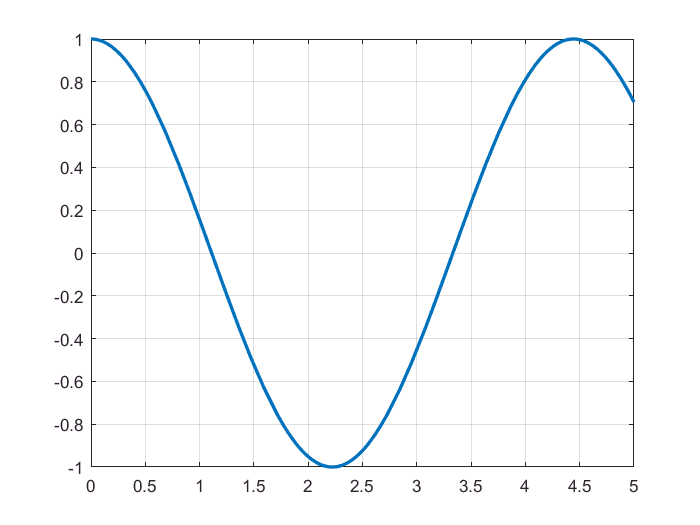

fplot(Sol,[0 5],LW,2); grid on

In this case you may get the solution. However, the symbolic math gives the solution if there are analytic solution, that means you may solve the differential equation as a closed form. If there is no explicit solution, you may not get the answer.  

**2. Linear time varying differential equation **

** 1)  symbolic math **

For example we may solve a time varying equation as


$$\frac{d^2 x}{dt^2 } = -tx(t), x(0) = 1, \frac{dx}{dt}(0) = 0$$


then the matlab code may be

clear all;
syms x(t)
LW ='linewidth';
eqn = diff(x,t,2) == -t*x;
Dy = diff(x,t);
con = [x(0) ==1, Dy(0)==0];
Sol = dsolve(eqn, con)

$$Sol = \frac{3^{2/3}\,\Gamma (\frac{2}{3})\,\text{airy}\left(0,-t\right)}{2}+\frac{3^{1/6}\,\Gamma (\frac{2}{3})\,\text{airy}\left(2,-t\right)}{2}$$

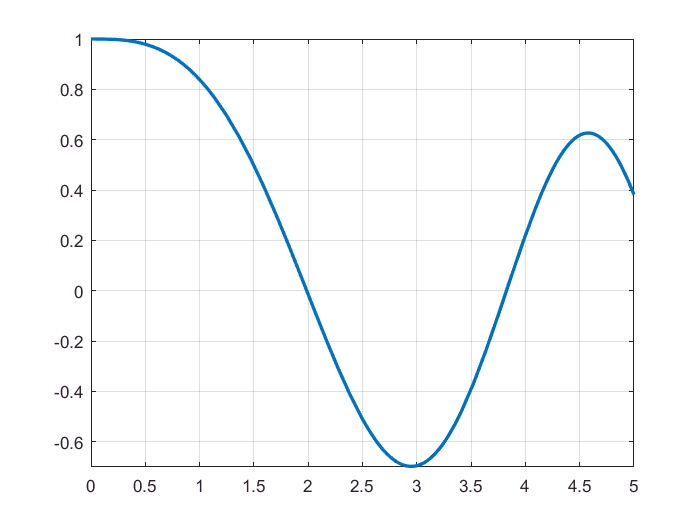

fplot(Sol,[0 5],LW,2); grid on

Here there are two special functions in the solution...Ok..At least we may have a solution graph.  Now consider the following equation 


$$\frac{d^2 x}{dt^2 } = -t^3 x(t), x(0) = 1, \frac{dx}{dt}(0) = 0$$


then the code will be

clear all;
syms x(t)
LW ='linewidth';
eqn = diff(x,t,2) == -t^3*x;
Dy = diff(x,t);
con = [x(0) ==1, Dy(0)==0];
Sol = dsolve(eqn, con)

Sol = [ empty sym ]

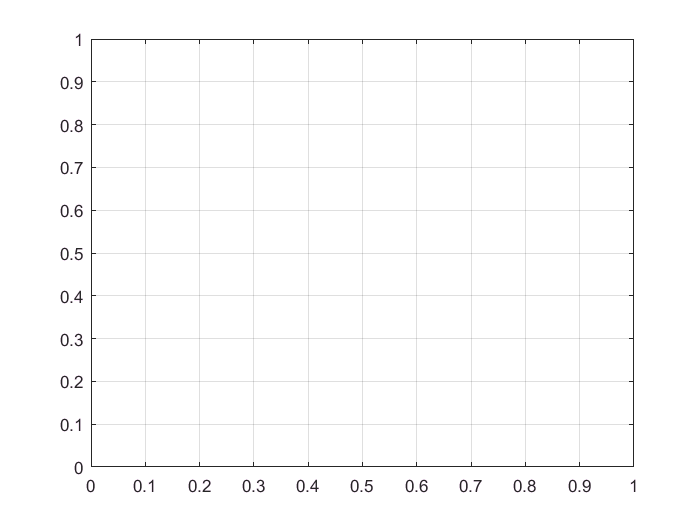

fplot(Sol,LW,2); grid on

Here, matlab says "**Explicit solution could not be found"** so that symbolic math is not the method to get the solution. Hence you may define "step" size and get the solution numerically. 

2)** Chebfun method**

clear all;
LW ='LineWidth';
L = chebop(0,10)

 
L =
 
   Empty operator operating on chebfun objects defined on:
      [0,10]



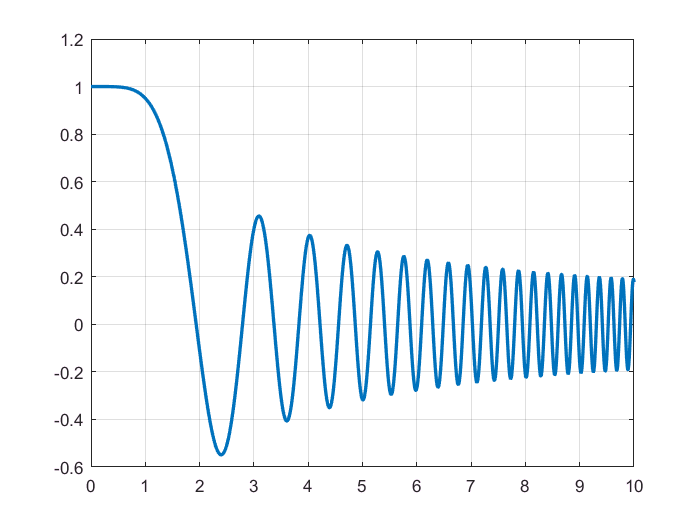

L.op =@(t,x) diff(x,2) + t^3*x;
L.lbc =[1;0];
x = L\0; 
plot(x,LW,2), grid on

**Here you get the answer!!** To verify the solution, let us check  at the boundaries

x(0)

ans = 1

y=diff(x,1);
y(0)

ans = 2.5989e-10

So the solution at the boundaries are the same value which are defined. I should say a little bit about the matlab code. Here "L" is defined as an operator in the domain of $[0  \ 10 ]$. The description of the  operator "L.op" is once again defined in detail as


$$\frac{d^2 x} { dt^2 } + t^3 x$$


And there are two boundary conditions 


$$x(0)  = 1, \frac{dx}{dt} (t=0) = 0$$


are coded as


$$L.lbc = [1 ; 0]$$
 

Now the input is "zero" , hence the solution $x$ with the operator constriant and boundary conditions is

                                                     x = L\0;

Looks simple!!

This simplicity over traditional matlab methods. In general, non-linear differential equations are difficult to gat their closed form of the solution, i.e., **"symboloc math" can not give the answer. **In this case,** by using numerical methods, you may define the step size.**